# Test 3: Multi-layered and spherically-symmetric (Io)

In this notebook the tidal response of a multi-layered, spherically-symmetric, viscoelastic body is computed using LOV3D and compared against results obtained with the [code](https://github.com/mroviranavarro/Poroviscoelastic_Tides) of [Rovira-Navarro et al. 2022](https://doi.org/10.1029/2021JE007117) ([code](https://github.com/mroviranavarro/Poroviscoelastic_Tides)) and [Beuthe et al. 2013](https://www.sciencedirect.com/science/article/pii/S0019103512004745?casa_token=xg0XfpmaHT4AAAAA:Qau6ppdURvhX_Vgm_NiDZVwEtERNnqcosVviHYGaLIHJLBugG7ZgBEnHNPG921Qc5SZAktQ6kw)

clearvars
clc
set(0,'defaulttextInterpreter','latex') 
mfile_name          = mfilename('fullpath');
if contains(mfile_name,'LiveEditorEvaluationHelper')
    mfile_name=matlab.desktop.editor.getActiveFilename;
end
[pathstr,name,ext]  = fileparts(mfile_name);
cd(pathstr);
cd('..')
addpath(genpath(pwd))
HOME = pwd;

## Interior model

The interior model is based on the Io model of [Steinke et al. 2023](https://doi.org/10.1016/j.icarus.2019.05.001) and [Beuthe et al. 2013](https://www.sciencedirect.com/science/article/pii/S0019103512004745?casa_token=xg0XfpmaHT4AAAAA:Qau6ppdURvhX_Vgm_NiDZVwEtERNnqcosVviHYGaLIHJLBugG7ZgBEnHNPG921Qc5SZAktQ6kw), which consists on a core, mantle, asthenosphere and lithosphere. Three different interior models are considered

- Interior Model A: Tidal heating only occurs in the asthenosphere (based on [Steinke et al. 2023](https://doi.org/10.1016/j.icarus.2019.05.001) ) 

- Interior Model B: Tidal heating occurs in both asthenosphere and deep mantle (based on [Steinke et al. 2023](https://doi.org/10.1016/j.icarus.2019.05.001))

- Interior Model C: Tidal heating occurs in both layers (based on  [Beuthe et al. 2013](https://www.sciencedirect.com/science/article/pii/S0019103512004745?casa_token=xg0XfpmaHT4AAAAA:Qau6ppdURvhX_Vgm_NiDZVwEtERNnqcosVviHYGaLIHJLBugG7ZgBEnHNPG921Qc5SZAktQ6kw))

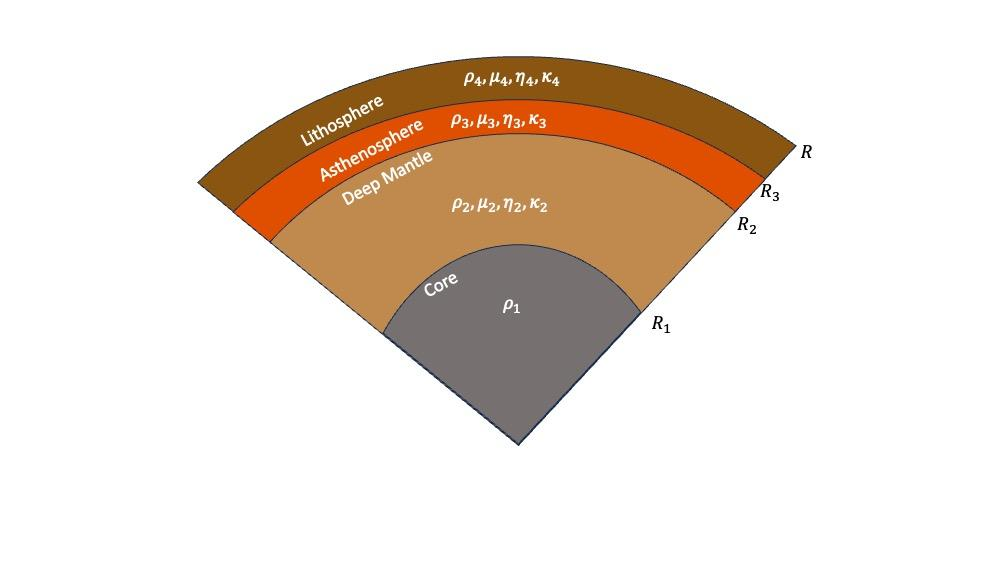

The model parameters are given in dimensional form 

Orbital frequency and period

% Values are taken from Steinke et al. (2020a)
omega0=4.1086E-05; %Io's orbital frequency 
T=2*pi/omega0; %Io's orbital period

Nominal interior model (From table in report)

% Interior_Model values for the core
Interior_Model_A(1).R0 = 965; % CMB in km 
Interior_Model_A(1).rho0 = 5150; % average density in kg m^-3

% Interior_Model values for mantle
Interior_Model_A(2).R0 = 1591.6; % outer radius of this layer
Interior_Model_A(2).rho0 = 3244; % density in kg m^-3
Interior_Model_A(2).mu0 = 2e9; % shear modulus in Pa
Interior_Model_A(2).eta0 = 8e14; % viscosity in Pa s

% Interior_Model values for asthenosphere
Interior_Model_A(3).R0 = 1791.6; % outer radius of this layer
Interior_Model_A(3).rho0 = 3244; % density in kg m^-3
Interior_Model_A(3).mu0 = 9e7; % shear modulus in Pa
Interior_Model_A(3).eta0 = 3.5e12; % viscosity in Pa s

% Interior_Model values for crust
Interior_Model_A(4).R0 = 1821.6; % outer radius of this layer
Interior_Model_A(4).rho0 = 3244; % density in kg m^-3
Interior_Model_A(4).mu0 = 6.5e10; % shear modulus in Pa
Interior_Model_A(4).eta0 = 1e23; % viscosity in Pa s

NominalModel = Interior_Model_A;

## Define forcing

The forcing potential is defined

Forcing(1).Td=T;
Forcing(1).n=2; 
Forcing(1).m=0; 
Forcing(1).F=1;

## Define numerics used to compute the tidal response 

- Nlayers: Number of concentric layers, including the core

- method: Method for setting the radial points per layer. Variable means fixed number of points per layer, variable separation.

- Nrbase: Determines the number of points per layer depending on the method (Default 2000)

- parallel_sol: Parallelize for loop to call get_Love (Default 0)

- parallel_gen: Parallelize calculation of potential coupling files and propagation in get_solution (Default 0)

- perturbation_order: Maximum order to which couplings are considered (Default 2)

- solution_cutoff: Maximum degree of solution. Not used if perturbation order is specified (Default 12)

- load_couplings: 0 = No, 1 = Loading of specific file, 2 = Searches for big enough file (Default 1)

- Nenergy: Maximum degree to which energy dissipation is expanded (Default 12)

- rheology_cutoff: Maximum order of difference (so in log) up to which rheology is still used (Default 2)

% Radial discretization
Numerics.Nlayers = length(NominalModel);
Numerics.method = 'variable';
Numerics.Nrbase = 500;

% Parallelization
Numerics.parallel_sol = 0;
Numerics.parallel_gen = 0;

% Lateral variations
Numerics.perturbation_order = 2;
Numerics.solution_cutoff = 12;
Numerics.load_couplings = 1;
Numerics.Nenergy = 12;
Numerics.rheology_cutoff = 2;


## Analyze influence of parameters

Nominal configuration

k2_nominal = analyze_model(NominalModel, Forcing, Numerics);
disp(['k_2 Model ' num2str(k2_nominal)]);

k_2 Model 0.61183-0.015009i


Influence of core radius

% Core configuration
core_params = ["R0", "rho0"];
ast_params = ["R0", "rho0", "mu0", "eta0"];


for layer_idx = 1:4

    if layer_idx == 1
        current_params = core_params;
    else
        current_params = ast_params;
    end

    for cparam = current_params

        sensitivity_k2(cparam, layer_idx, NominalModel, Forcing, Numerics, HOME);

    end

end

Layer idx :: 1 --- Param name :: R0
Layer idx :: 1 --- Param name :: rho0
Layer idx :: 2 --- Param name :: R0
Layer idx :: 2 --- Param name :: rho0
Layer idx :: 2 --- Param name :: mu0
Layer idx :: 2 --- Param name :: eta0
Layer idx :: 3 --- Param name :: R0
Layer idx :: 3 --- Param name :: rho0
Layer idx :: 3 --- Param name :: mu0
Layer idx :: 3 --- Param name :: eta0
Layer idx :: 4 --- Param name :: R0
Layer idx :: 4 --- Param name :: rho0
Layer idx :: 4 --- Param name :: mu0
Layer idx :: 4 --- Param name :: eta0


function [] = sensitivity_k2(param_name, layer_idx, NominalModel, Forcing, Numerics, HOME)

    disp("Layer idx :: " + num2str(layer_idx) + " --- Param name :: " + param_name);

    nominal_value = NominalModel(layer_idx).(param_name);
    if param_name == "eta0" || param_name == "mu0"
        param_range = [nominal_value / 100, nominal_value / 10, nominal_value, nominal_value * 10, nominal_value * 100];
    elseif param_name == "R0"
        if layer_idx == 3
            param_range = linspace(0.75 * nominal_value, 1800., 10);
        elseif layer_idx == 2
            param_range = linspace(0.75 * nominal_value, 1770., 10);
        else
            param_range = linspace(0.75 * nominal_value, 1.25 * nominal_value, 10);
        end
    else
        param_range = linspace(0.75 * nominal_value, 1.25 * nominal_value, 10);
    end
    k2_range_real = zeros(size(param_range));
    k2_range_imag = zeros(size(param_range));
    
    for idx = 1:length(param_range)

        % disp("Running with " + param_name + " = " + num2str(param_range(idx)));
        current_model = NominalModel;
        current_model(layer_idx).(param_name) = param_range(idx);
        current_k2 = analyze_model(current_model, Forcing, Numerics);
        k2_range_real(idx) = real(current_k2);
        k2_range_imag(idx) = imag(current_k2);

    end
    
    save(HOME + "/output/layer" + num2str(layer_idx) + "_" + param_name + ".txt",...
        "param_range", "k2_range_real", "k2_range_imag", "-ascii");

end

Influence of core density